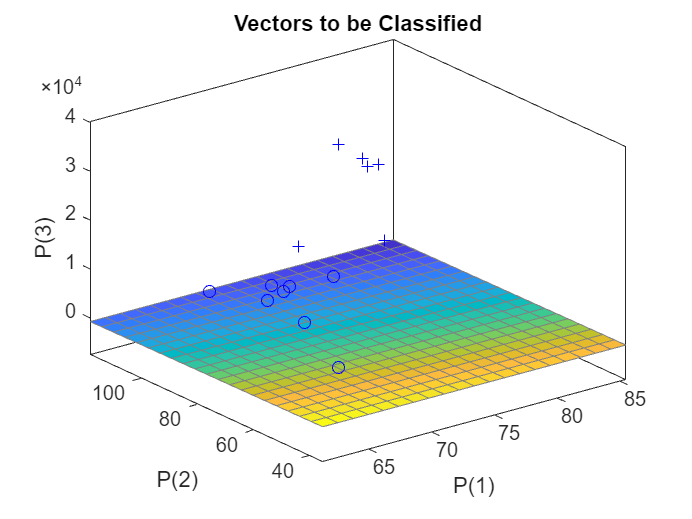

%国家类型的自适应分类(原始数据)
clear                                       %清理内存
UNDP2                                       %将保存的数据导入内存
P=[C1;C2]';                                 %构造输入变量
T=[ones(length(C1),1)
   zeros(length(C2),1)]';                   %定义一个分类变量表示的目标输出
plotpv(P,T);                                %绘制感知器的输入向量和目标向量
net=newp(minmax(P),1);                      %创建一个感知器网络
handle=plotpc(net.iw{1},net.b{1});          %在训练前的分类图中绘制分界面
net.adaptParam.passes=2;                    %设定自适应循环次数为2次
handle=plotpc(net.iw{1},net.b{1});
for a=1:290                                 %指定迭代次数为290次
    [net,Y,e]=adapt(net,P,T);               %调用自适应函数训练网络
    handle=plotpc(net.iw{1},net.b{1},handle);
    drawnow;                                %添加分类界面
end;

Y                                           %输出自适应结果

Y =      1     1     1     1     1     1     1     1     1     1     0     1     1     1


P_test=S';                                  %调用待判样品数据
y=sim(net,P_test);y                         %待判样品的仿真结果

y =      0     0     0     0


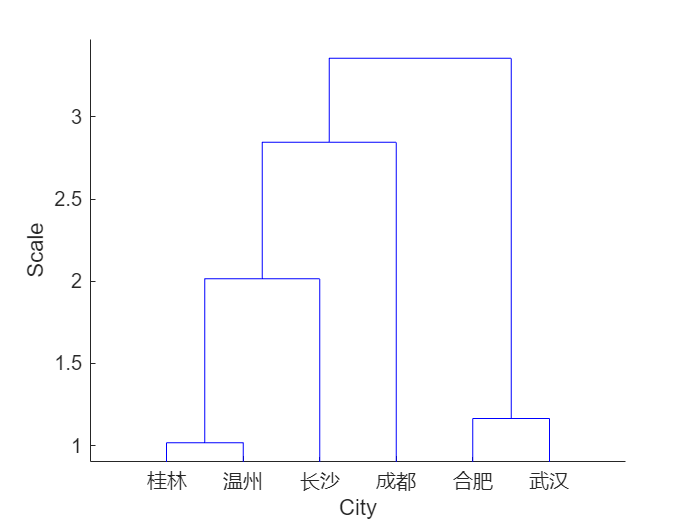



%层次聚类：重心法&欧氏距离
S=['合肥';'武汉';'长沙';'桂林';'温州';'成都'];
X=[15.7  970   2209  -20.6  1.9
16.3  1260  2085  -17.3  2.8
17.2  1422  1726  -9.5   4.6
18.8  1874  1709  -4.9   8.0
17.9  1698  1848  -4.5   7.5
16.3  976   1239  -4.6   5.6];  
figure(2)
x=zscore(X);                                %原始数据集体标准化 
D=pdist(x,'euclid');                        %计算样品之间的欧式距离
M=squareform(D);                            %排出欧式距离矩阵
Z=linkage(D,'centroid');                    %根据重心法聚类
H=dendrogram(Z,'labels',S);                 %画出聚类谱系图并添加样品标签           
xlabel('City');                             %谱系图的横轴标签
ylabel('Scale');                            %谱系图的纵轴标签

C=cophenet(Z,D);                            %计算Cophenetic相关系数
T=cluster(Z,2)                              %指定分类数目

T =      1
     1
     2
     2
     2
     2
